# Perform SLAM on Rough Terrains

This example demonstrates implementing *simultaneous localization and mapping* (SLAM) on 3-D lidar sensor data using point cloud processing algorithms and trajectory optimization. The goal of this example is to estimate the trajectory of the vehicle and create a 3-D occupancy map of the construction site. 

## What is SLAM

SLAM is short for Simultaneous Localization and Mapping and is commonly used for autonomous vehicles. It is a computational method to build and update map and localize the vehicle in that map at the same time. Common sensors include Lidar, camera, IMU, and even GPU. After sensor data is collected, broadly speaking, there are two components used to achieve SLAM. The first type is sensor signal processing. We can obtain motion estimation of the vehicle as well as the obstacle location estimation. Here, SLAM methods can be categorized depending on the sensors used. Visual SLAM uses images acquired from cameras and other images sensors. Light detection and ranging (lidar) SLAM primarily uses a laser or distance sensor. The output of a lidar sensor is a point cloud at each measurement. A 3D point cloud is a collection of points each having an X, Y, and Z coordinates. The second component is pose graph registration and optimization. A vehicle’s pose is its location and orientation, and a pose graph contains a set of poses coming from measurements by different sensors and/or at different times. In an ideal situation, all the poses in the graph are accurate. However, due to the uncertainty in real-world sensing, we only have an estimate of the poses and how confident we are with the estimate. Based on these, we move the poses relative to each other to better align features and obstacles. When we do this for the complete set of measurements, we get the full trajectories, and this is pose graph optimization. 

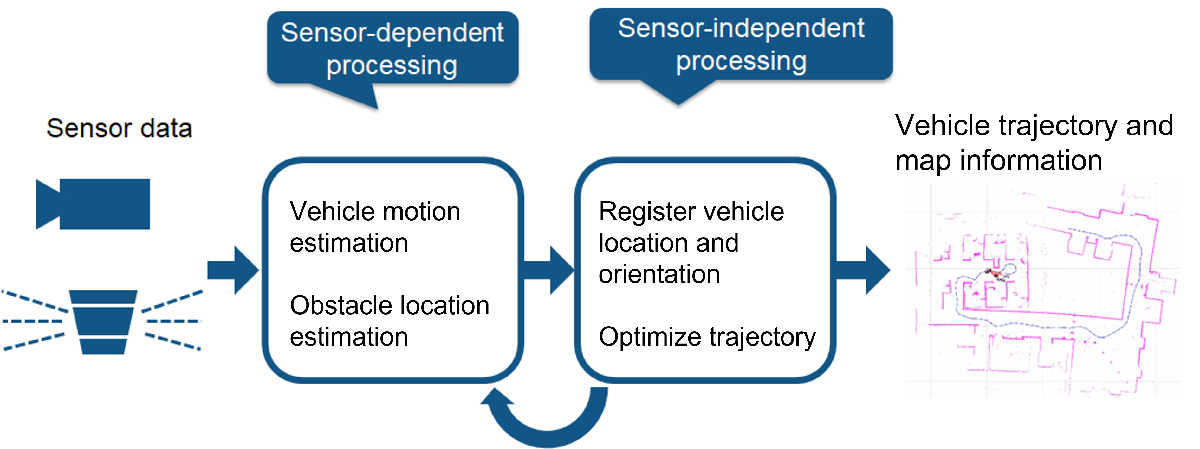

## Problem Definition 

There are some specific challenges when driving on rough terrain or offroad conditions. Typical challenges include:

- Sensor disturbance: disturbances to Lidar, camera and other sensor readings introduced by the vehicle motion on a bumpy road

- Limited availability of GPS signals

- Multi-sensor fusion of IMU, lidar, camera, and GPS

In this video, we will demonstrate the challenges introduced to SLAM by driving on a rough terrain, and potential methods to mitigate the challenges.

- Input: ROS bag containing Lidar, camera, IMU, and odometry for the duration of a vehicle driving through the construction site 

- Output: a 3-D map that should resemble the construction site 

- Goal: minimize error between the generated map and the ground truth 

## Load Data 

Select the ROS data collected from the third-party 

addpath('SLAMData');
addpath('Maps');
bagName = 'main_scene_two_obstacle.bag';

Convert the ROS bag data to MATLAB timetables for Lidar, IMU, and odometry. Save the timetables in three MATLAB data files: 

bag2timetable(bagName); 

Load and process the timetable for Lidar data. The output of a lidar sensor is a point cloud at each measurement. A 3-D point cloud is a collection of points each having an X, Y, and Z coordinates.The lidar data contains a cell array of `n`-by-3 matrices, where *n* is the number of 3-D points in the captured lidar data, and the columns represent *xyz*-coordinates associated with each captured point.

load('lidarRos_main_scene_two_obstacle.mat')
n_scans = 1200;
pClouds = cell(1,n_scans);
for i_scan = 1:n_scans
    pClouds{i_scan} = lidarPointClouds.PointCloud(i_scan).Location;
end

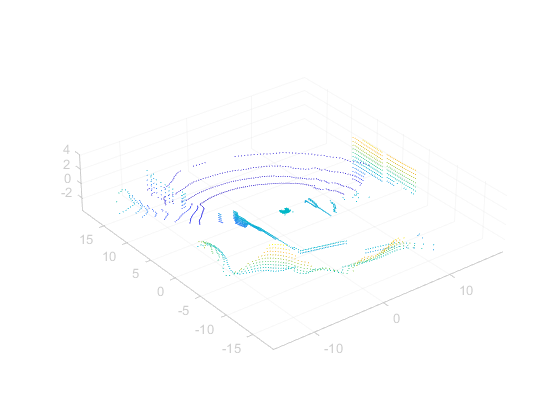

## Parameters For Ponit Cloud Registration

The approach to building a map in this example consists of the follwoing steps:

- **Align lidar scans: **align successive lidar scans using a Normal Distribution Transform (NDT) point cloud registration technique. The technique returns the rigid transformation that aligns the moving point cloud with respect to the reference point cloud. See [pcregsiterndt](https://www.mathworks.com/help/vision/ref/pcregisterndt.html) for moe details. By successively composing theses transformations, each point cloud is transformed back to the reference frame of the first point cloud. 

- **Combine aligned scans: **generate a map by combining all the transformed point clouds. 

For poind cloud registration, the following parameters are defined. 

- `maxLidarRange` specifies the maximum range of the 3-D laser scanner. 

- `referenceVector` is normal to the ground plane.

- `maxDistance` is the maximum distance for inliers when removing the ground and ceiling planes.

- `maxAngularDistance` is the maximum angle deviation from the reference vector when fitting the ground and ceiling planes. 

- `randomSampleRatio `specifies the sample ratio that the point clouds are downsampled using random sampling, in order to improve the efficiency and accuracy of the registration algorithm.*

- `gridStep` specifies the voxel grid sizes used in the NDT registration algorithm.* 

- `distanceMovedThreshold `specifies the minimum the vehicle has to move for the scan to be accepted.

* I will show how changing these parameters impact the accuracy of the final result. 

maxLidarRange = 100;
referenceVector = [0 0 1];
maxDistance = 0.1;
maxAngularDistance = 15;
randomSampleRatio = 1;
gridStep = 2.5;
distanceMovedThreshold = 0;

## Effects of chaning `randomSampleRatio` on map construction. 

`randomSampleRatio` takes on a value between zero and one. Increasing `randomSampleRatio` means we are increasing down sampling of the points in the point clouds, which is often used to improve the speed and accuracy of the point cloud registration algorithm. Down sampling should be tuned for specific needs. In this case, when we use a `randomSampleRatio` of 0.3, the algorithm fails soon after we start building it. As we progressively increase randomSampleRatio, we get better maps. 

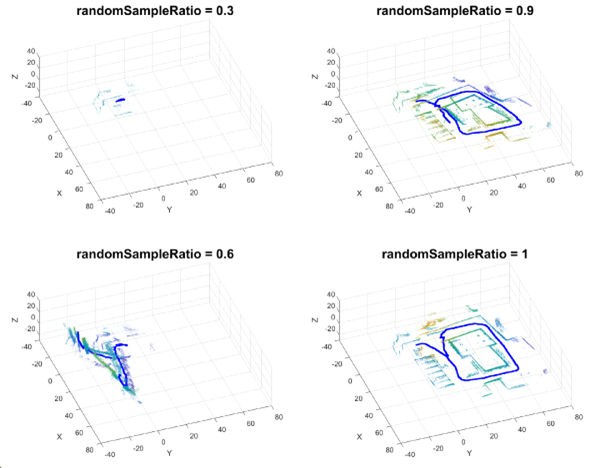

## Parameters For Loop Closure Estimation 

A loop closure is when the vehicle visits and recognizes a previously mapped region. In loop closure query, the robot looks around itself, compares this region with visited places, and determines the current region has been visited. The search is performed by matching the current scan with the previous scans within a small radius. The SLAM algorithm uses this information to reduce the uncertainty in mapping. This section contains the parameters for searching for loop closure. 

loopClosureSearchRadius = 3;

The loop closure algorithm is based on 2-D submap and scan matching. A submap is created after every `nScansPerSubmap` (Number of Scans per submap) accepted scans. The loop closure algorithm disregards the most recent `subMapThresh` scans while searching for loop candidates. 

nScansPerSubmap = 3;
subMapThresh = 50;

An annular region with *z*-limits specified by `annularRegionLimits` is extracted from the point clouds. Points outside these limits on the floor and ceiling are removed after the point cloud plane fit algorithms idenfity the region of interest.

annularRegionLimits = [-0.75 0.75];

The maximum acceptable Root Mean Squared Error (RMSE) in estimating relative pose between loop candidates is specified by `rmseThreshold`. Choose a lower value for estimating accurate loop closure edges, which has a high impact on pose graph optimization.

rmseThreshold = 0.26;

The threshold over scan matching score to accept a loop closure is specified by `loopClosureThreshold`. Pose Graph Optimization is called after inserting `optimizationInterval` loop closure edges into the pose graph.

loopClosureThreshold = 15;
optimizationInterval = 2;

## Initialize Variables 

The function below initialize variables:

- Set up a pose graph, occupancy map, and nessary variables. 

- Preallocate variables for the processed point clouds, lidar scans, and submaps. Create a downsampled set of point clouds for quickly visualizing the map.

- Set random seed to guarantee consistent random sampling.

- Create variables for display purposes. 

- Initialize figure windows if desired.

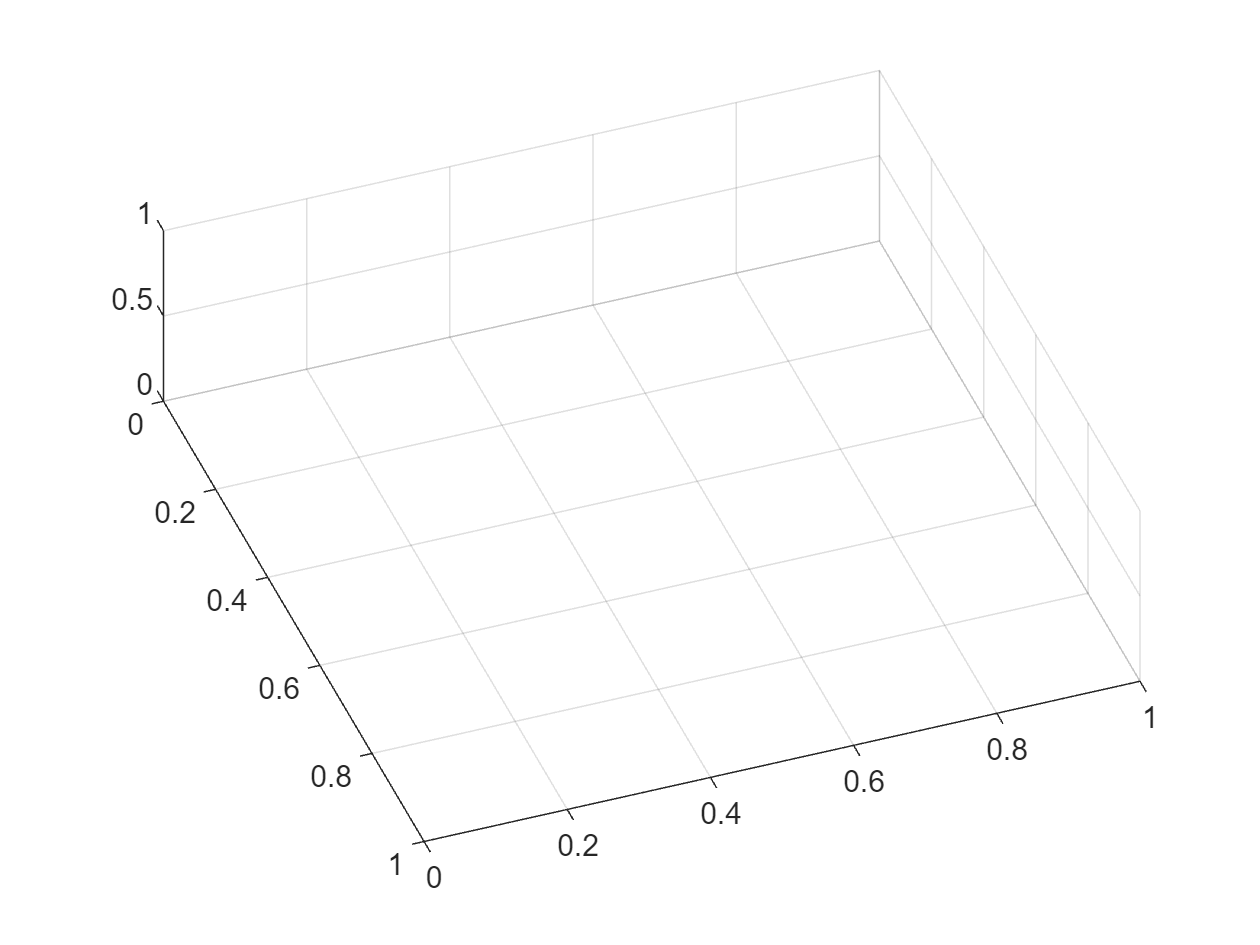

initializeVariables;

## Trajectory Estimation And Refinement 

The trajectory of the vehicle is a collection of vehicle poses (location and orientation), estimated at every 3-D lidar scan acquisition instance. The 3-D lidar SLAM algorithm has the following steps: 

- Point cloud filtering

- Point cloud downsampling

- Point cloud registration

- Loop closure query 

- Pose graph optimization

Iteratively process the point clouds to estimate the trajectory.

count = 0; % Counter to track number of scans added
disp('Estimating robot trajectory...');

Estimating robot trajectory...


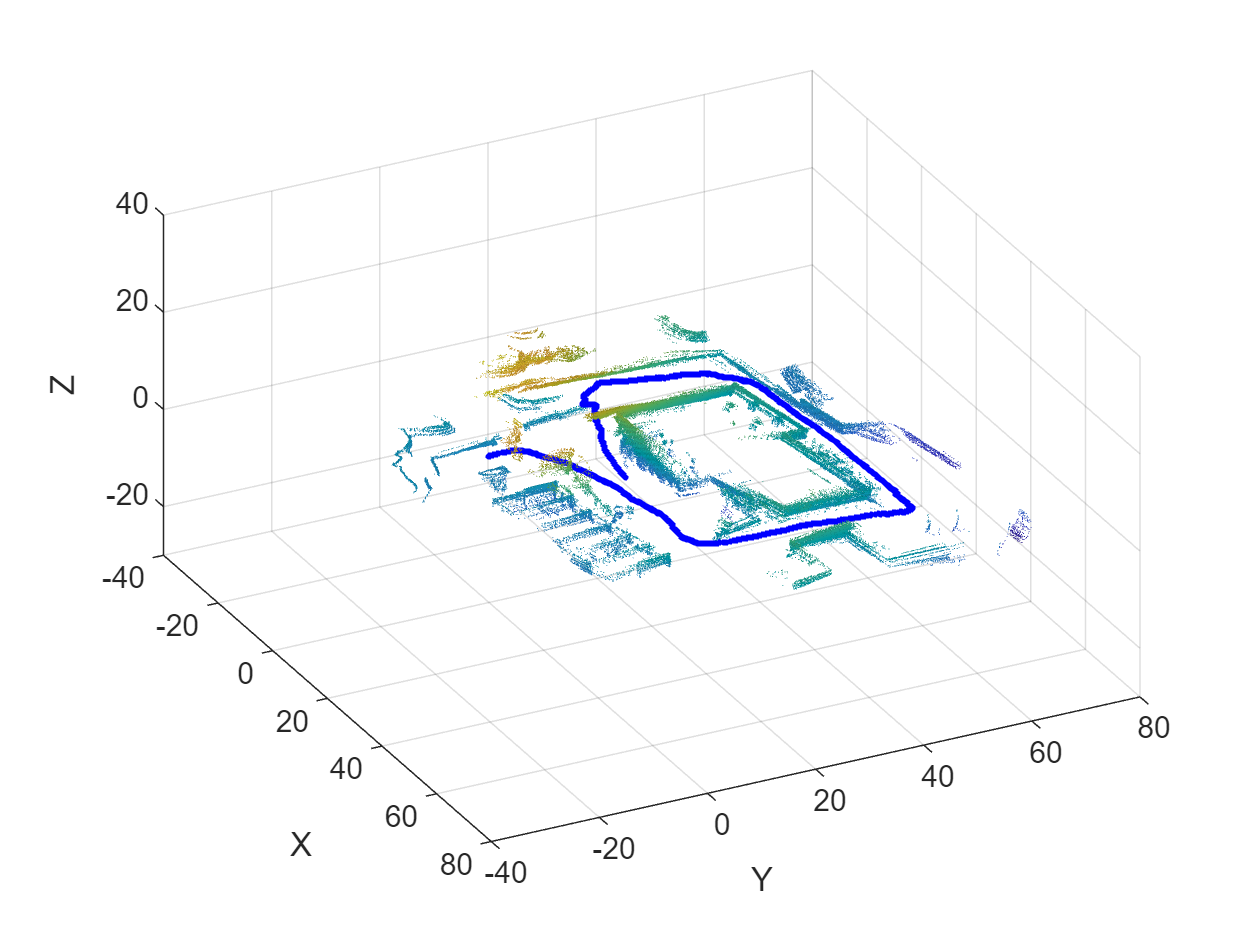

for i=1:length(pClouds)
    pc = pClouds{i}; % Read point clouds in sequence

### Point Cloud Filtering

Point cloud filtering is done to extract the region of interest from the acquired scans. We are most interested in mapping out the buildings, their walls and corners. To focus on these, we will remove the ground and sky. It is common to select the region of interest as the annular region with ground removed. However, it is very challenging when the ground is uneven. In this example, we also enable removing points below a certain height. 

Remove points from ground return. 

    pcl = pointCloud(pc(:,:));
    [~, ~, outliers] = pcfitplane(pcl, maxDistance,referenceVector,maxAngularDistance);
    pcl_wogrd = select(pcl,outliers,'OutputSize','full');
    tm = pcl.Location(:,3) > -3;
    indTm = find(tm>0.5);
    pcl_wogrd = select(pcl,indTm);

Remove points on the ceiling plane.

    [~, ~, outliers] = pcfitplane(pcl_wogrd,0.2,referenceVector,maxAngularDistance);
    pcl_wogrd = select(pcl_wogrd,outliers,'OutputSize','full');

Select points in annular region.

Select region of interest. 

    ind = (pcl_wogrd.Location(:,3)<annularRegionLimits(2))&(pcl_wogrd.Location(:,3)>annularRegionLimits(1));
    pcl_wogrd = select(pcl_wogrd,ind,'OutputSize','full');


### Point Cloud Downsampling

Point cloud downsampling improves the speed and accuracy of the point cloud registration algorithm. Down sampling should be tuned for specific needs.  

    pcl_wogrd_sampled = pcdownsample(pcl_wogrd,'random',randomSampleRatio);
    
    if viewPC==1 % Visualize down sampled point cloud
        view(pplayer,pcl_wogrd_sampled);
        pause(0.001)
    end

### Point Cloud Registration

This is a process to align scans and find the relative position of all future scans relative to the previous scans. Point cloud registration estimates the relative pose (rotation and translation) between current scan and previous scan. The first scan is always accepted (processed further and stored) but the other scans are only accepted after translating more than the specified threshold. `poseGraph3D` is used to store the estimated accepted relative poses (trajectory). We specified `distanceMovedThreshold `to be 0, so all scans are accepted. 

    if count == 0 % First can
        tform = [];
        scanAccepted = 1;
    else
        if count == 1
            tform = pcregisterndt(pcl_wogrd_sampled,prevPc,gridStep);
        else
            tform = pcregisterndt(pcl_wogrd_sampled,prevPc,gridStep,...
                'InitialTransform',prevTform);
        end
        
        relPose = [tform2trvec(tform.T') tform2quat(tform.T')];
        
        if sqrt(norm(relPose(1:3))) > distanceMovedThreshold
            addRelativePose(pGraph,relPose);
            scanAccepted = 1;
        else
            scanAccepted = 0;
        end
    end

### Loop Closure Query

In loop closure query, the robot looks around itself, compares this region with visited places, and determines if this region has been visited. The search is performed by matching the current scan with the previous scans within a small radius around the current vehicle location specified by `loopClosureSearchRadius`. Searching within a small radius is sufficient when there is low drift in lidar odometry. However, searching against a larger radius is necessary when there is high lidar odometry drift, and search against more previous scans is time consuming. Loop closure query consists of the following steps:

- Create submaps from `nScansPerSubmap` consecutive scans.

- Match the current scan with the submaps within the `loopClosureSearchRadius`.

- Accept the matches if the match score is greater than the `loopClosureThreshold`. All the scans representing accepted submap are considered as probable loop candidates.

- Estimate the relative pose between probable loop candidates and the current scan. A relative pose is accepted as a loop closure constraint only when the RMSE is less than the `rmseThreshold`.  

    if scanAccepted == 1
        count = count + 1;
        pcProcessed{count} = pcl_wogrd_sampled;
        lidarScans2d{count} = exampleHelperCreate2DScan(pcl_wogrd_sampled);
        
        % Submaps are created for faster loop closure query. 
        if rem(count,nScansPerSubmap)==0
            submaps{count/nScansPerSubmap} = exampleHelperCreateSubmap(lidarScans2d,...
                pGraph,count,nScansPerSubmap,maxLidarRange);
        end
        
        % loopSubmapIds contains matching submap ids if any otherwise empty.   
        if (floor(count/nScansPerSubmap)>subMapThresh)
            [loopSubmapIds,~] = exampleHelperEstimateLoopCandidates(pGraph,...
                count,submaps,lidarScans2d{count},nScansPerSubmap,...
                loopClosureSearchRadius,loopClosureThreshold,subMapThresh);
            
            if ~isempty(loopSubmapIds)
                rmseMin = inf;
                
                % Estimate best match to the current scan
                for k = 1:length(loopSubmapIds)
                    % For every scan within the submap
                    for j = 1:nScansPerSubmap
                        probableLoopCandidate = ...
                            loopSubmapIds(k)*nScansPerSubmap - j + 1;
                        [loopTform,~,rmse] = pcregisterndt(pcl_wogrd_sampled,...
                            pcProcessed{probableLoopCandidate},gridStep);
                        % Update best Loop Closure Candidate
                        if rmse < rmseMin
                            loopCandidate = probableLoopCandidate;
                            rmseMin = rmse;
                        end
                        if rmseMin < rmseThreshold
                            break;
                        end
                    end
                end
                
                % Check if loop candidate is valid
                if rmseMin < rmseThreshold
                    disp('A Loop Closure Detected')
                    % loop closure constraint
                    relPose = [tform2trvec(loopTform.T') tform2quat(loopTform.T')];
                    
                    addRelativePose(pGraph,relPose,infoMat,...
                        loopCandidate,count);
                    numLoopClosuresSinceLastOptimization = numLoopClosuresSinceLastOptimization + 1;
                end
                     
            end
        end
        

### Pose Graph Optimization

After a loop closure is detected, we use this information to do an optimization, in order to reduce the effects of uncertainty in lidar sensing. This way, we increase the confidence in the estimated trajectory and generated map. This process is called pose graph optimization. Pose graph optimization runs after a sufficient number of loop edges are accepted to reduce the drift in trajectory estimation.

        if (numLoopClosuresSinceLastOptimization == optimizationInterval)||...
                ((numLoopClosuresSinceLastOptimization>0)&&(i==length(pClouds)))
            if loopClosureSearchRadius ~=1
                disp('Doing Pose Graph Optimization to reduce drift.');
            end
            % pose graph optimization
            pGraph = optimizePoseGraph(pGraph);
            loopClosureSearchRadius = 6;
            if viewMap == 1
                position = pGraph.nodes;
                % Rebuild map after pose graph optimization
                omap = occupancyMap3D(mapResolution);
                for n = 1:(pGraph.NumNodes-1)
                    insertPointCloud(omap,position(n,:),pcsToView{n}.removeInvalidPoints,maxLidarRange);
                end
                mapUpdated = true;
                ax = newplot;
                grid on;
            end
            numLoopClosuresSinceLastOptimization = 0;
            % Reduce the frequency of optimization after optimizing the trajectory
            optimizationInterval = optimizationInterval*7;
        end

Visualize the map and pose graph during the build process. This visualization is costly, so enable it only when necessary by setting `viewMap` to 1. If visualization is enabled then the plot is updated after every 15 added scans.

        pcToView = pcdownsample(pcl_wogrd_sampled, 'random', 0.5);
        pcsToView{count} = pcToView;
        
        if viewMap==1
            % Insert point cloud to the occupance map in the right position
            position = pGraph.nodes(count);
            insertPointCloud(omap,position,pcToView.removeInvalidPoints,maxLidarRange);
            
            if (rem(count-1,15)==0)||mapUpdated
                exampleHelperVisualizeMapAndPoseGraph(omap, pGraph, ax);

xlim([-40.0 80.0])
ylim([-40 80])
zlim([-30.0 40.0])
            end
            mapUpdated = false;
        else
            % Give feedback to know that example is running
            if (rem(count-1,15)==0)
                fprintf('.');
            end
        end
        

Update previous relative pose estimate and point cloud.

        prevPc = pcl_wogrd_sampled;
        prevTform = tform;
    end
end

## Compare the Map to Ground Truth

We compare the generated map to the ground truth in 2D. 

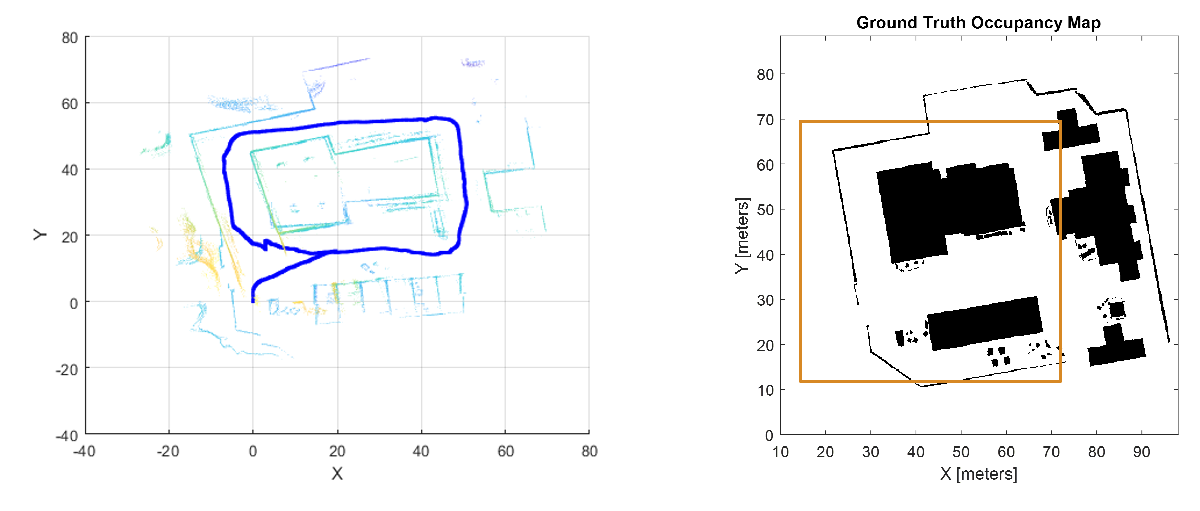

## Build and Visualize 3-D Occupancy Map  

The point clouds are inserted into `occupancyMap3D` using the estimated global poses. After iterating through all the nodes, the full map and estimated vehicle trajectory is shown.

if (viewMap ~= 1)||(numLoopClosuresSinceLastOptimization>0)
    nodesPositions = nodes(pGraph);
    % Create 3D Occupancy grid
    omapToView = occupancyMap3D(mapResolution);
    
    for i = 1:(size(nodesPositions,1)-1)
        pc = pcsToView{i};
        position = nodesPositions(i,:);
        
        % Insert point cloud to the occupance map in the right position
        insertPointCloud(omapToView,position,pc.removeInvalidPoints,maxLidarRange);
    end
    
    figure;
    axisFinal = newplot;
    exampleHelperVisualizeMapAndPoseGraph(omapToView, pGraph, axisFinal);
end

## Tuning Parameters

- The parameter randomSampleRatio is between 0 and 1. It is defined in Line 15. A higher value indicates sparser point clouds. The figures below are generated using `randomSampleRatio` value of 0.3, 0.6, 0.9, and 1 respectively. A smaller value is recommended when you need a very dense occupancy map and the odmoetry is very accurate. In this example, because the odometry from SLAM is subject to a lot of noises, a higher value of downsampling is recommended.  

        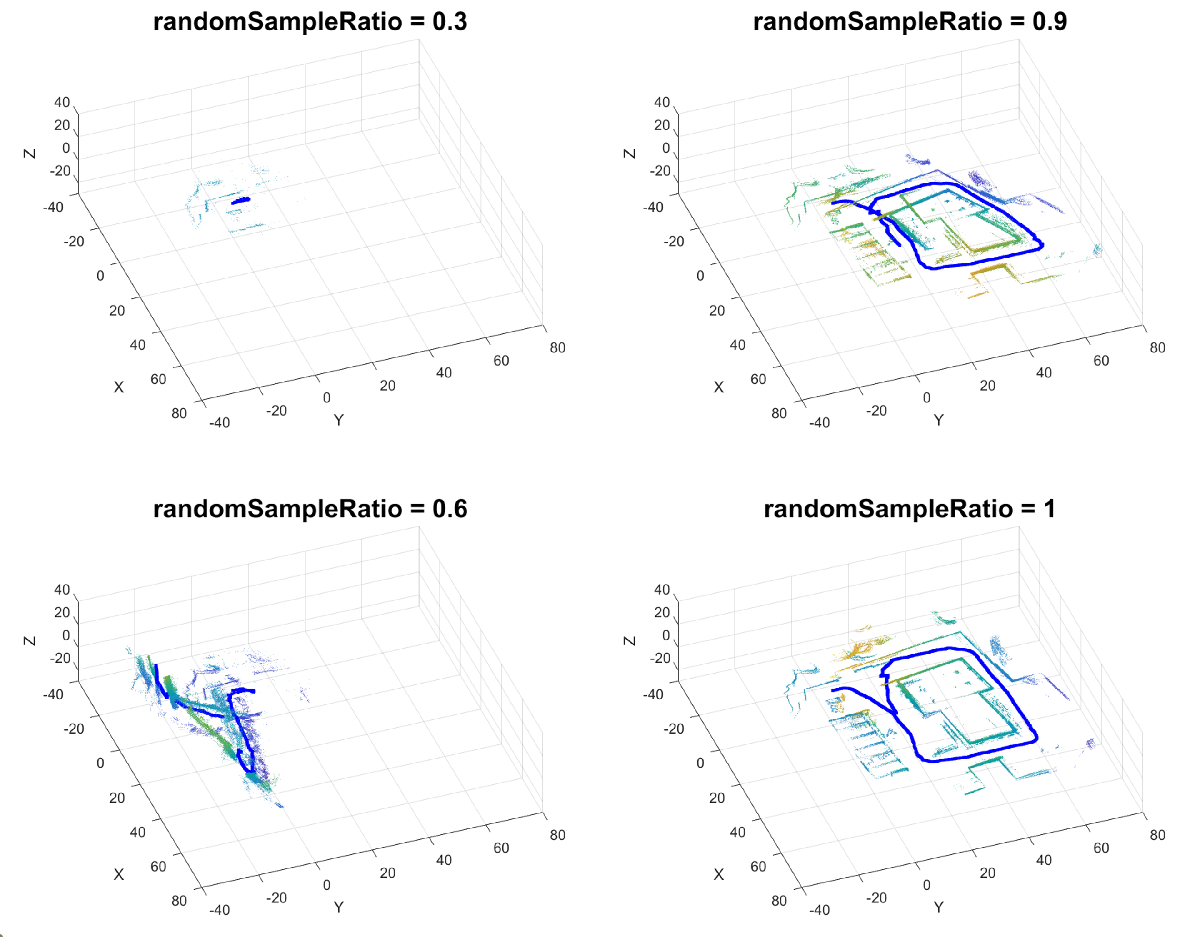

- The map construction is very sensitive to the parameter `gridStep`. It is defined in Line 16. The parameter specifies the voxel grid sizes used in the NDT registration algorithm. 

       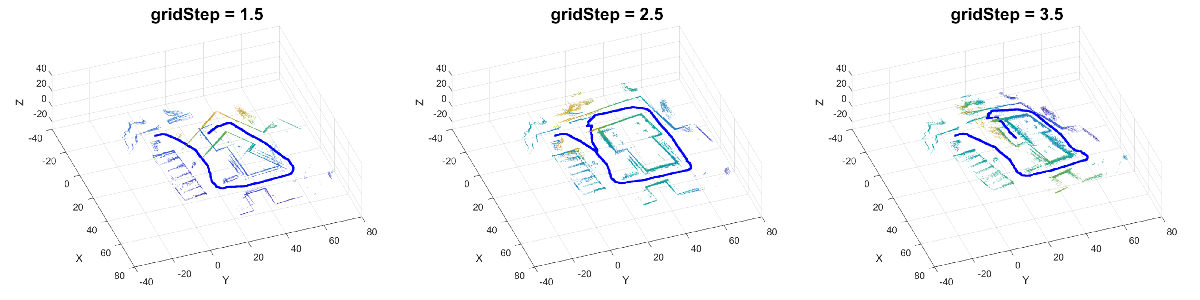

- The loop closure query parameters are defined from Line 18 to 24. If we enlarge the loop closure search space using the following parameters, we can detect one loop closure after adding scan 1174. The figure below shows the built map before loop closure using 1170 scans and after loop closure using 1200 scans. We can observe the complete trajectory has been optimized after loop closure detection and pose graph optimization. 

            `loopClosureSearchRadius = 6;`

            `nScansPerSubmap = 3;`

            `subMapThresh = 50;`

            `annularRegionLimits = [-2 2];`

            `rmseThreshold = 10;`

            `loopClosureThreshold = 15;`

            `optimizationInterval = 2;`